clear variables
rng(1);

%parameters
tmax = 100000;
n = 2;
nres = 2;

c = [.2 .1; .1 .2];
d = [.2; .2];
r = [1; 1];
K = [10; 10];

state0 = [1; 1; .2; .2];

%simulate
tspan = [0 tmax];
[t,y] = ode45(@(t,state0) f(state0,c,r,K,d,n,nres), tspan, state0);

c_inv = [.2 .1];
d_inv = .2;

real_eql_R1 = y(end,3)

real_eql_R1 = 0.6665

real_eql_R2 = y(end,4)

real_eql_R2 = 0.6665


eql_R1 = (c(2,2) * d(1) - c(1,2) * d(2)) / (c(1,1) * c(2,2) - c(1,2) * c(2,1))

eql_R1 = 0.6667

eql_R2 = (c(1,1) * d(2) - c(2,1) * d(1)) / (c(1,1) * c(2,2) - c(1,2) * c(2,1))

eql_R2 = 0.6667


inv_growth = c_inv(1) * real_eql_R1 + c_inv(2) * real_eql_R2 - d_inv

inv_growth = -4.0337e-05

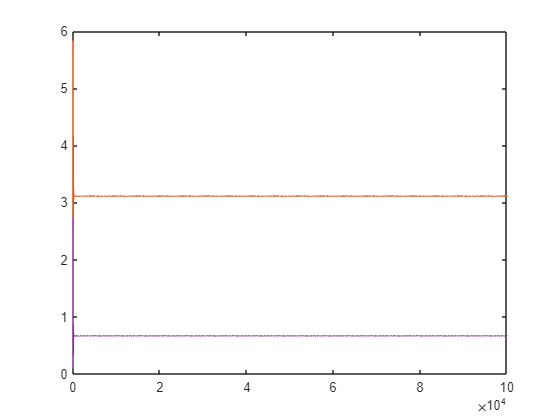


[c_31, c_32] = meshgrid(linspace(0,1,20),linspace(0,1,20));
d_3 = c_31 * eql_R1 + c_32 * eql_R2;

plot(t, y)

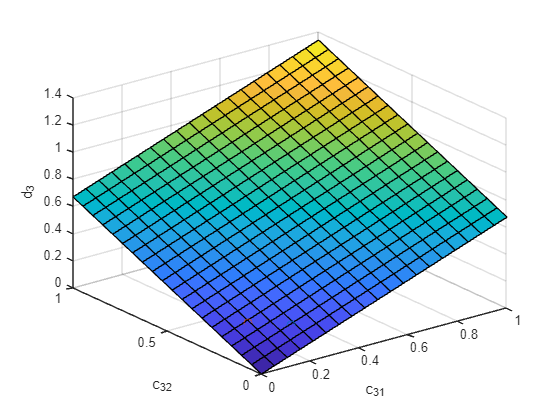


surf(c_31,c_32,d_3);

hold on
plot3(c(1,1), c(1,2), d(1), 'o')
plot3(c(2,1), c(2,2), d(2), 'o')

xlabel('c_{31}') 
ylabel('c_{32}') 
zlabel('d_3')


%plot3(y(:,1), y(:,2), y(:,3))
%xlabel('N1') 
%ylabel('N2') 
%zlabel('R')

function dState = f(state,affinities,r,K,death,n,nres)
    dState = zeros(n+nres,1);
    N = state(1:n);
    R = state(n+1:n+nres);
    dN = (affinities * R - death) .* N;
    dR = r .* R .* (1 - R ./ K) - affinities.' * N .* R;
    dState(1:n) = dN;
    dState(n+1:n+nres) = dR;
end